# Inverse Beam Former

clearvars
dataFileName = "C:\Users\pbergman\GIT25\ZDATA00\radarReturn_20251112_081611.mat";
load(dataFileName);

[lat1_, lon1_, ~, ~] = ROTH.ohsElementPositions();
alt1_ = lat1_.*0.0;

elementData = ROTH.inverseBeamForm( radarReturn_, ROP, az_, lat1_, lon1_, alt1_);

nl = 3;
SOP.noiseLevel = nl;

backGroundNoise = nl*randn(size(elementData)) + nl*randn(size(elementData))*1i;
elementData = elementData + backGroundNoise;

fileName = sprintf("elementData%02d", nl);
elementDataFileName = ROTH.createDataFileName( fileName, ROP );

save( elementDataFileName, "ROP", "SOP", "elementData", "-v7.3");

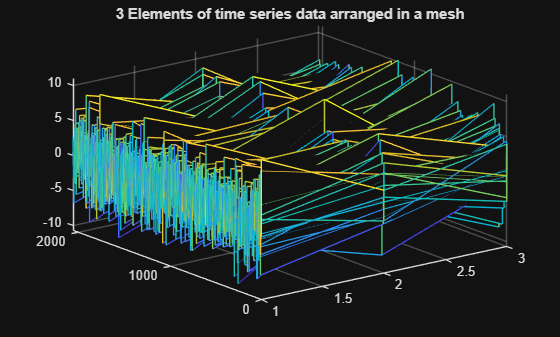

mesh(real(elementData(1:2048,1:3)));
title("3 Elements of time series data arranged in a mesh");


% elementPhaseWeight00 = conj( ROTH.calculatePhaseWeights(  0, ROP.Fc, lat1_, lon1_, alt1_) );
% elementPhaseWeight10 = conj( ROTH.calculatePhaseWeights( 10, ROP.Fc, lat1_, lon1_, alt1_) );
% elementPhaseWeight20 = conj( ROTH.calculatePhaseWeights( 20, ROP.Fc, lat1_, lon1_, alt1_) );
% elementPhaseWeight30 = conj( ROTH.calculatePhaseWeights( 30, ROP.Fc, lat1_, lon1_, alt1_) );
% elementPhaseWeight40 = conj( ROTH.calculatePhaseWeights( 40, ROP.Fc, lat1_, lon1_, alt1_) );
% elementPhaseWeight50 = conj( ROTH.calculatePhaseWeights( 50, ROP.Fc, lat1_, lon1_, alt1_) );